# **Práctica 1 - "Señales en tiempo continuo"**

**Analisis de señales y sistemas - 2MV1**

**Integrantes:**

- Edgar Vargas Rodriguez

- Emilio Vidal Ortiz

- Gustavo Robles Ramirez

- Jaqueline Tinoco Vázquez

- Mauricio Paulo Peña Sánchez

**Objetivos:**

- Manipulación básica de MATLAB

- Gráficas de señales reales y complejas continuas

- Transformación de señales continuas (escalamientos y traslaciones)

- Calculo de energía y potencia de señales continuas

## **Introducción.**

En esta parte se investigó cómo hacer graficas en python y con su conocimeinto poder replicar la gráfica de  lo que será la sección 4 de esta práctica. Se realizó la grafica con ayuda de una herramienta colaborativa de Google. Se podrá acceder a través del siguiente enlace:

[Acceda a través de este enlace](https://colab.research.google.com/drive/1Fj9wuLe3IAaooFLIa1oCunPq4Re0VLWH?usp=sharing)

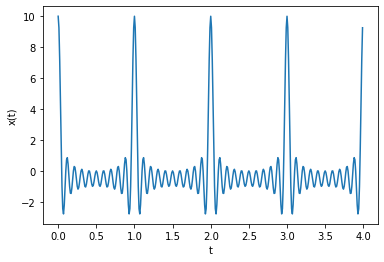

## Sección 1.

En esta sección se reproducira la sección 1.11, resumida convenientemente, del libro *Linear Systems and Signals* de Lathi (al final se citará propiamente).

***1.11-1 Funciones anonimas***

Una función anónima brinda una representación simbólica definida en términos de operadores, funciones u otras funciones anónimas. Por ejemplo; *f (t) = e^−t cos(2πt).*

f = @(t) exp(-t).*cos(2*pi*t);

Una vez definida la función anónima *f (t), *puede ser evaluada simplemente asignándole valores de entrada, por ejemplo:

t = 0; f(t)

ans = 1

Se obtiene el mismo resultado evaluando de la siguiente manera:

f(0)

ans = 1

Los vectores de entrada permiten evaluar en multiples valores simultáneamente. Para graficar *f(t) *sobre los valores enteros que se encuentran en el intervalo* (−2 ≤ t ≤ 2) *se asigna el vector *t* de la siguiente forma:

t = (-2:1:2);
f(t)

ans =     7.3891    2.7183    1.0000    0.3679    0.1353


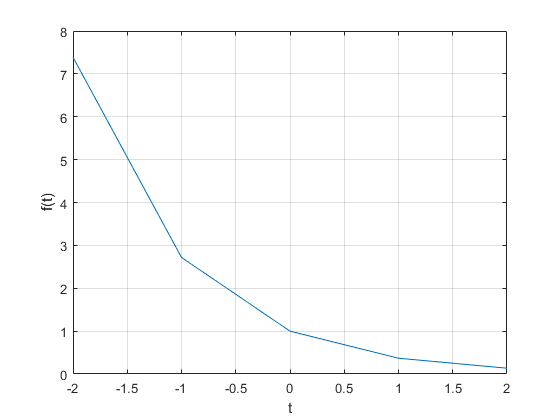

plot(t,f(t));
xlabel('t'); ylabel('f(t)'); grid;

Para analizar la conducta oscilatoria de la función se necesitan muchos más puntos. Para esta función oscilatoria se eligió dar 100 puntos por oscilación.

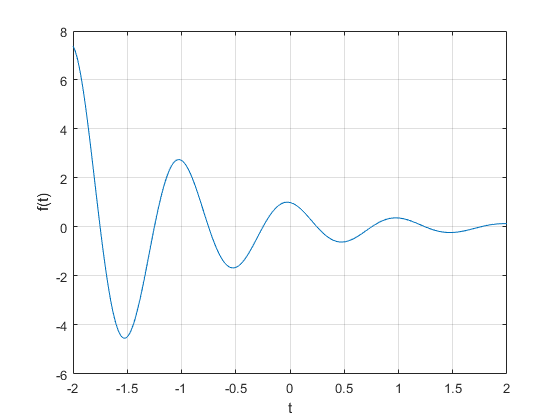

t = (-2:0.01:2);
plot(t,f(t));
xlabel('t'); ylabel('f(t)'); grid;

***1.11-2 Operadores relacionales y la función de escalón unitario***

Un operador relacional compara dos objetos. Si la comparación es verdadera, arroja un (1) lógico, si es falsa, arroja un (0) lógico. La función de escalón unitario se define por:

u = @(t) 1.0.*(t>=0);

Considerando la gráfica de* u(t) *con* t = (-2:2)*

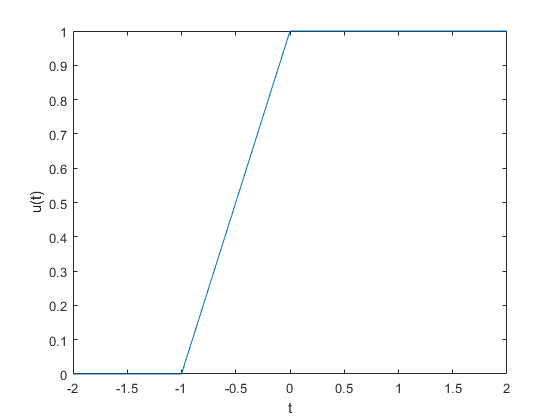

t = (-2:2); plot(t,u(t));
xlabel('t'); ylabel('u(t)');

Se corrigen algunos errores que presenta la gráfica.

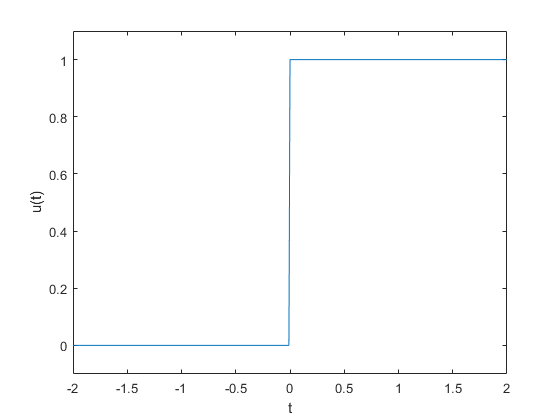

t = (-2:0.01:2); plot(t,u(t));
xlabel('t'); ylabel('u(t)');
axis([-2 2 -0.1 1.1]);

Considerar la definición y gráfica del pulso unitario *p(t) = u(t)−u(t −1)*:

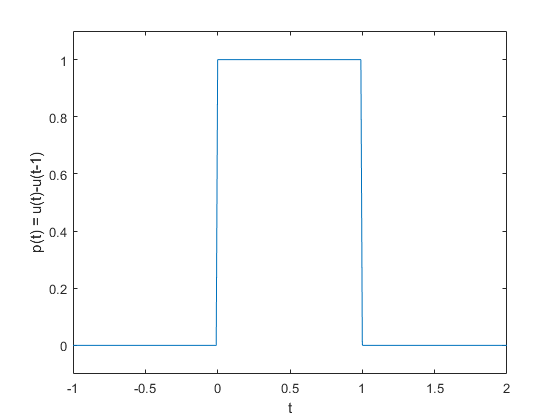

p = @(t) 1.0.*((t>=0)&(t<1));
t = (-1:0.01:2); plot(t,p(t));
xlabel('t'); ylabel('p(t) = u(t)-u(t-1)');
axis([-1 2 -.1 1.1]);

Las funciones anónimas se pueden construir utilizando otras funciones anónimas, se pudo utilizar el escalón unitario previamente definido como *p(t) as p = @(t)u(t)-u(t-1)*

***1.11-3 Operaciones de variable Independiente***

Considerando *g(t) = f (t)u(t) = e^−t cos (2πt)u(t)* una version causal de f(t). La multiplicación de las dos funciones *f(t) y u(t) *están dadas por *g(t):*

f = @(t) exp(-t).*cos(2*pi*t);
u = @(t) 1.0.*(t>=0);
g = @(t) f(t).*u(t);

Una operación combinada de escalamiento y traslación está dada por *g(at + b), *donde a y b son constantes reales. Como ejemplo, se graficará *g(2t+1) sobre (−2 ≤ t ≤ 2),* en este caso la función se comprime en un factor de 2.

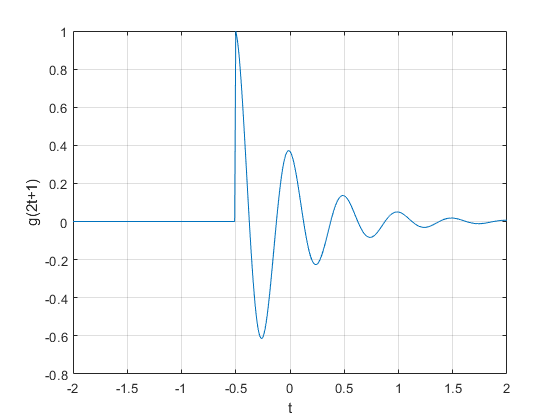

t = (-2:0.01:2);
plot(t,g(2*t+1)); xlabel('t'); ylabel('g(2t+1)'); grid;

Ahora se graficará *g(−t + 1) *sobre* (−2 ≤ t ≤ 2). *Entonces la función se refleja y se mueve una unidad a la derecha.

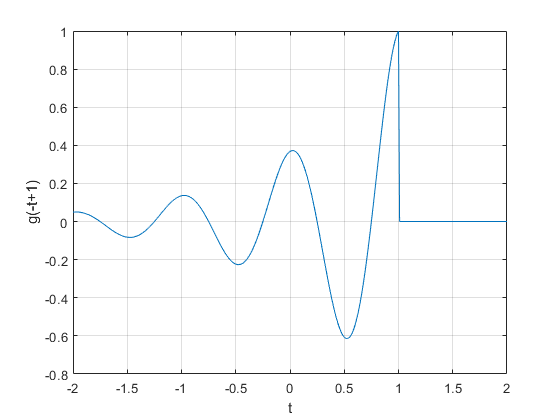

plot(t,g(-t+1)); xlabel('t'); ylabel('g(-t+1)'); grid;

Por último se graficará* h(t) = g(2t + 1) + g(−t + 1) sobre (−2 ≤ t ≤ 2).*

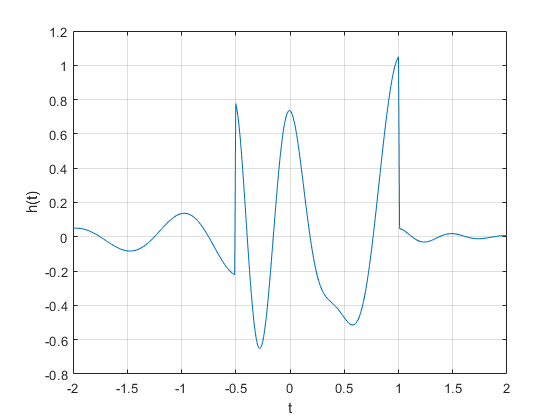

plot(t,g(2*t+1)+g(-t+1)); xlabel('t'); ylabel('h(t)'); grid;

***1.11-4 Integración numérica y calcular señal de energía***

Calcular la energía de la señal, que implica integrar el cuadrado de estas expresiones, puede ser una tarea abrumadora. Por suerte, muchas integrales difíciles se pueden estimar con precisión mediante técnicas de integración numérica.

Tenemos una señal $x\left(t\right)=e^{-t} \left(u\left(t\right)-u\left(t-1\right)\right)$ y su energia está expresada como $\;E_x =\int_{-\infty }^{\infty } \left|x\left(t\right){\left|\right.}^{2\;} d\left(t\right)\right.$, la energia de esta señal es $E_x \approx 0\ldotp 4323$. Esta energia se puede evaluar numericamente, para ello, creamos una funcion x(t).

f = @(t) exp(-t).*cos(2*pi*t);
u = @(t) 1.0.*(t>=0);
g = @(t) f(t).*u(t);
x = @(t) exp(-t).*((t>=0)&(t<1));

Con $\bigtriangleup t=0\ldotp 01\;$se crea un vector

clear t
t = (0:0.01:1);

El resutado final esta dado por el comando de suma:

E_x = sum(x(t).*x(t)*0.01)

E_x = 0.4367

El resultado no es perfecto pero es un error del 1%, si cambiamos el vector y lo hacemos que tienda a cero, el error nos da menor al del principio.

Aunque la aproximacion rectangular no es la mejor manera de interar numericamente, el quad de MATLAB nos da la cuadratura de Simpson, Para su operación, quad requiere una función que describa el integrando, el límite inferior de integración y el límite superior de integración, Para usar quad para estimar Ex, primero se debe describir el integrando.

x_squared = @(t) x(t).*x(t);

Estimando $E_x$inmediatamente

E_x = quad(x_squared,0,1)

E_x = 0.4323

En este caso el error es de -0.00026% 

La misma tecnica puede ser usada para señales más complejas, considera a $g\left(t\right)$, MATLAB puede dar una respuesta mas rapida.

La envolvente que decae exponencialmente asegura g (t) es efectivamente cero mucho antes de t = 100. Por lo tanto, se utiliza un límite superior de t = 100 junto con t = 0.001.

g_squared = @(t) g(t).*g(t);
clear t
t = (0:0.001:100);
E_g = sum(g_squared(t)*0.001)

E_g = 0.2567

Una mejor aproximación es obtenida con la funcion quad.

E_g = quad(g_squared,0,100)

E_g = 0.2562

## Sección 2.

En esta sección se dará solución al ejercicio 1.2-2, apoyandonos de la información recuperada de la sección anterior.

1.2-2. Para la señal x(t) ilustrada en la figura, bosqueja:

*a) x(t-4)*

*b) x(t/1.5)*

*c) x(-t)*

*d) x(2t-4)*

*e) x(2-t)*

u = @(t) 1.0.*(t>=0);
a = @(t) -t.*(u(t+4)-u(t));
b = @(t) t.*(u(t)-u(t-2));
x = @(t) a(t)+b(t);
t = (-7:0.01:7);

***Así es la gráfica inicial de x(t):***

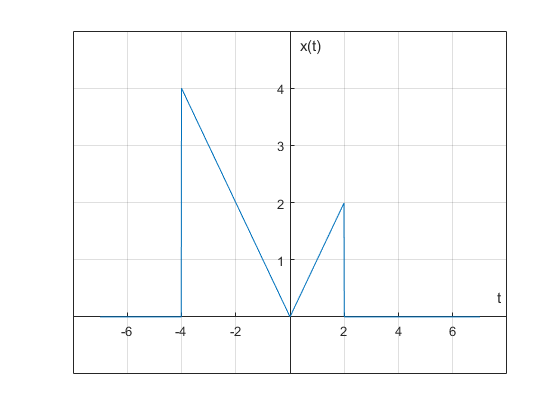

plot(t,x(t)); xlabel('t'); ylabel('x(t)'); hold on;
plano=gca;
plano.XAxisLocation="origin";
plano.YAxisLocation="origin";
ylim([-1,5]); grid;

***a) Gráfica de x(t-4)***

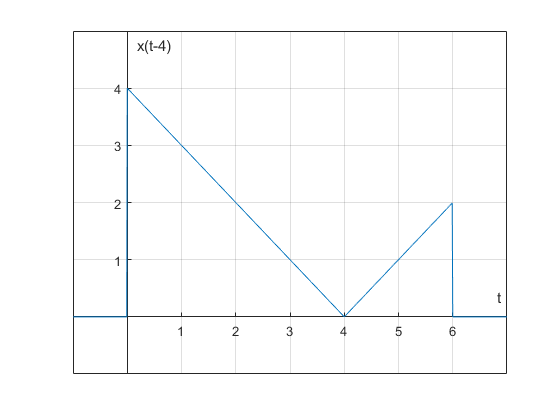

figure; plot(t,x(t-4)); xlabel('t'); ylabel('x(t-4)'); hold on;
plano=gca;
plano.XAxisLocation="origin";
plano.YAxisLocation="origin";
xlim([-1,7]);ylim([-1,5]); grid;

***b) Gráfica de x(t/1.5)***

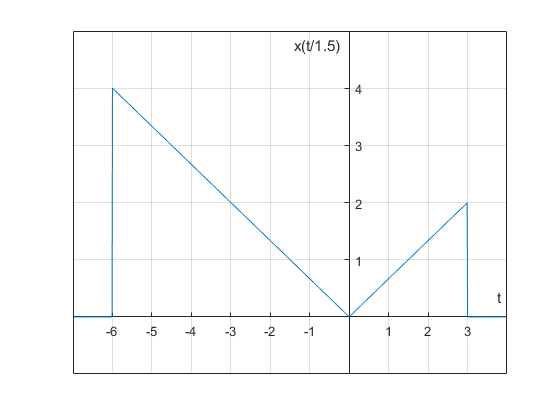

figure; plot(t,x(t./1.5)); xlabel('t'); ylabel('x(t/1.5)'); hold on;
plano=gca;
plano.XAxisLocation="origin";
plano.YAxisLocation="origin";
xlim([-7,4]);ylim([-1,5]); grid;

***c) Gráfica de x(-t)***

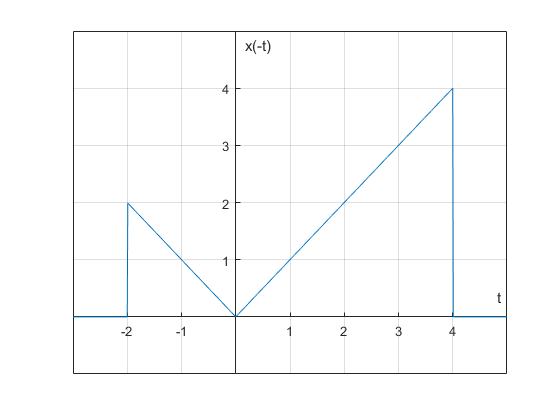

figure; plot(t,x(-t)); xlabel('t'); ylabel('x(-t)'); hold on;
plano=gca;
plano.XAxisLocation="origin";
plano.YAxisLocation="origin";
xlim([-3,5]);ylim([-1,5]); grid;

***d) Gráfica de x(2t-4)***

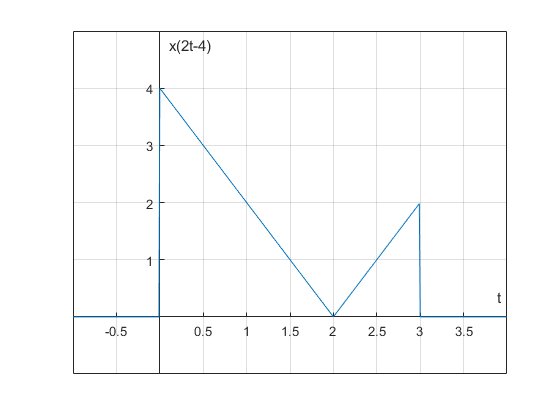

figure; plot(t,x(2.*t-4)); xlabel('t'); ylabel('x(2t-4)'); hold on;
plano=gca;
plano.XAxisLocation="origin";
plano.YAxisLocation="origin";
xlim([-1,4]);ylim([-1,5]); grid;

***e) Gráfica de x(2-t)***

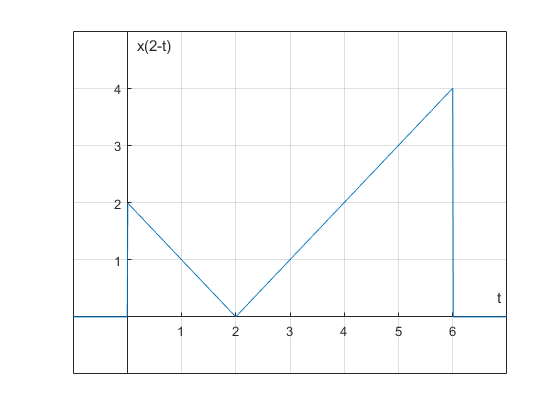

figure; plot(t,x(2-t)); xlabel('t'); ylabel('x(2-t)'); hold on;
plano=gca;
plano.XAxisLocation="origin";
plano.YAxisLocation="origin";
xlim([-1,7]);ylim([-1,5]); grid;

## Sección 3.

En está sección se pretende resolver le problema 1.11-1, con instrucción de mostrar los ejes en el origen y usar edición a preferencia.

1.11.1. Proporcione el código y la salida de MATLAB que traza la parte impar xo(t) de la función* x(t) = 2-t cos(2πt)u(t-π)* en un intervalo de longitud adecuada utilizando un número adecuado de puntos.

f = @(t) exp(-t).*cos(2*pi*t);
t = 0; 
f(t)

ans = 1

f(0)

ans = 1

Después, en la primera grafica, le damos un grosor de linea de 2 y que este de un color rojo, tambien le ponemos un titulo; para que los ejes se vean en el origen, se usa el codigo ya visto en clases.

t = (-2:2);
y=f(t)

y =     7.3891    2.7183    1.0000    0.3679    0.1353


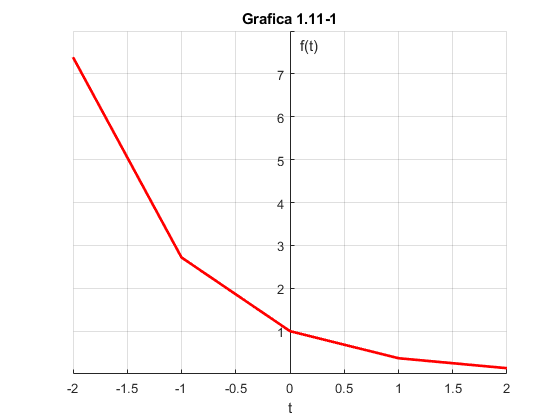

figure;
plot(t,y,'-r','LineWidth',2);
plano = gca;
plano.XAxisLocation = "origin";
plano.YAxisLocation = "origin";
plano.Box = "off";
grid on
xlabel('t');
ylabel('f(t)'); 
title('Grafica 1.11-1')

Para la segunda grafica, se hizo identicamente lo mismo para los ejes, se le cambio el titulo, pero ahora cambiamos el color de la linea a verde y con un grosor mayor.

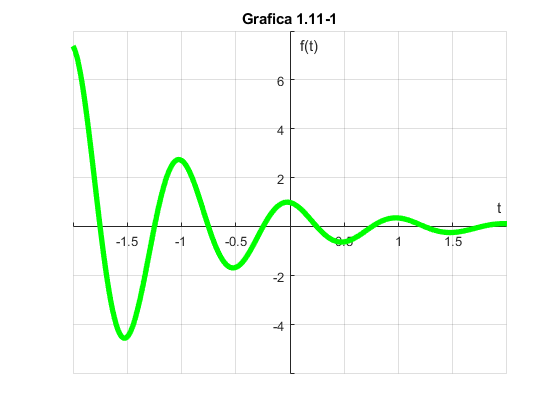

t = (-2:0.01:2);
figure;
plot(t,f(t),'-g','LineWidth',4);
plano = gca;
plano.XAxisLocation = "origin";
plano.YAxisLocation = "origin";
plano.Box = "off";
grid on
xlabel('t'); 
ylabel('f(t)'); 
title('Grafica 1.11-1')

## Sección 4.

En esta sección se construirá la gráfica de $x\left(t\right)=\sum_{k=1}^{10} \cos \left(2\pi \textrm{kt}\right)$, para cuatro rangos. Los ejes deben mostrarse en el origen además de la edición de su preferencia. 

syms t k
f= @(x) symsum(cos(2*pi*k*t),k,1,10);
f(t)

$$ans = \cos\left(2\,\pi \,t\right)+\cos\left(4\,\pi \,t\right)+\cos\left(6\,\pi \,t\right)+\cos\left(8\,\pi \,t\right)+\cos\left(10\,\pi \,t\right)+\cos\left(12\,\pi \,t\right)+\cos\left(14\,\pi \,t\right)+\cos\left(16\,\pi \,t\right)+\cos\left(18\,\pi \,t\right)+\cos\left(20\,\pi \,t\right)$$

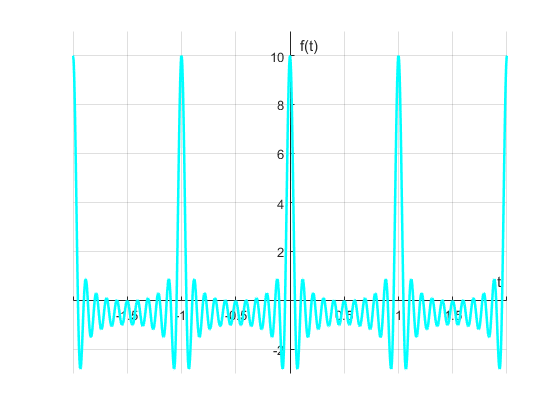

figure;
fplot(f(t),[-2 2],'-c','LineWidth',2')
xlabel('t'); ylabel('f(t)'); grid;
plano = gca;
plano.XAxisLocation = "origin";
plano.YAxisLocation = "origin";
plano.Box = "off";
grid on
xlim([-2 2])
ylim([-3 11.0])

La gráfica se aprecia consistente en toda su estructura.

## Sección 5.

En esta sección se dará solución al problema 1.11-3 y un ejercicio extra en el inciso e.

1.11-3 Define ${x\left(t\right)=e}^{t\left(1+\textrm{j2}\pi \right)} u\left(t\right)$ & $y\left(t\right)=\textrm{Re}\left\lbrace 2x\left(\frac{-5-t}{2}\right)\right\rbrace$

syms t pi 
x= @(t) exp(t*(1+2*1i*pi)).*heaviside(-t);
t=-10:0.01:10;
y= @(t) real(2*x((-5-t)/2));

**a) Grafique **$\textrm{Re}\left\lbrace x\left(t\right)\right\rbrace$** vs **$\textrm{Im}\left\lbrace x\left(\textrm{at}\right)\right\rbrace$

**a.3) Para a=2**

Re1= real(x(t));
Im1= imag(x(2*t));
figure
plot(Re1,Im1)

Error using plot
Data must be numeric, datetime, duration or an array convertible to double.

xlabel('Re x(t)')
ylabel('Im x(t)')

**a.2) Para a=1**

Re= real(x(t));
Im= imag(x(1*t));
figure
plot(Re,Im)
xlabel('Re x(t)')
ylabel('Im x(t)')

**a.1) Para a=0.5**

Re2= real(x(t));
Im2= imag(x(0.5*t));
figure
plot(Re2,Im2)
xlabel('Re x(t)')
ylabel('Im x(t)')

**¿Qué tan importante es la escala del factor a en la forma de la figura resultante?**

La importancia d eestos valores radica en que como se puede observar, nuestra gráfica luce mejor estructurada, con una forma más concisa. Es bastante exidente la diferencia entre la gráfica cuando se tiene un valor de a=2 a comparación de a=0.5

**b) Gráfique y(t) de -10<=t<=10**

figure
x= @(t) exp(t*(1+2*1i*pi)).*heaviside(-t);
y= @(t) real(2*x((-5-t)/2));
fplot(y,[-10 10])
xlabel('-10<t<10')
ylabel('y(t)')

**c) Energía Ex de la señal x(t)**

syms t 
x= @(t) exp(t*(1+2*1i*pi)).*heaviside(-t);
h= (real(x(t))^2+imag(x(t))^2)
Ex=int(h,t,-Inf,Inf)

**d) Energía Ey de la señal x(t)**

syms t
x= @(t) exp(t*(1+2*1i*pi)).*heaviside(-t);
y= @(t) real(2*x((-5-t)/2))
f=y(t)*y(t)
Ey=int(f,t,-Inf,Inf)

**e)  Gráfique x(t) para t **$\in$** [-10,10]**

syms t
x= @(t) exp(t*(1+2*1i*pi)).*heaviside(-t);
t=(-10:0.01:10);
figure
plot3(real(x(t)),imag(x(t)),t)
grid on
zlabel('Dominio t')
xlabel('Re')
ylabel('Im')
title('Gráfica de la señal f(t)=e^{t*(1+2*j*pi)}*u(-t) ')

## Sección 6.

En esta sección simplemente se ilustrará el resultado del desarrollo de una aplicación que permite al usuario ingresar una función y realizar las transformaciones que desee.

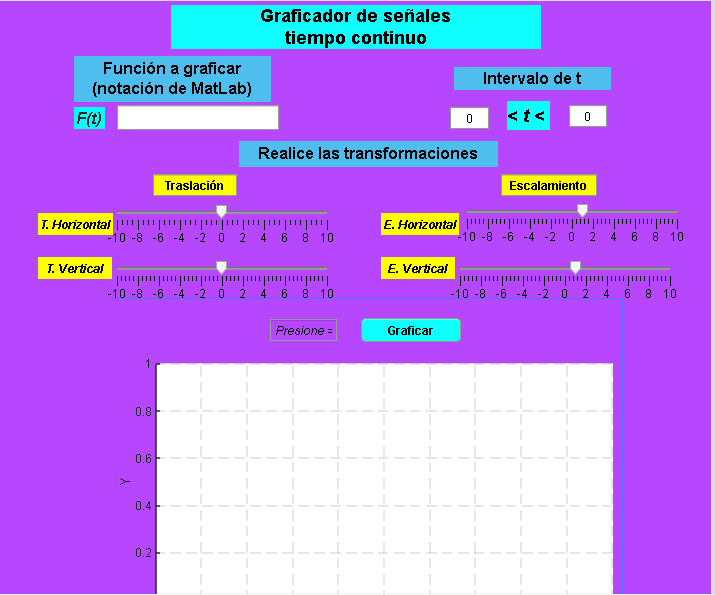

## Referencias.

Lathi, B. P., & Green, R. A., (2018). *Linear Systems and Signals*. EUA: Oxford University Press.